## Script for load following MSDR

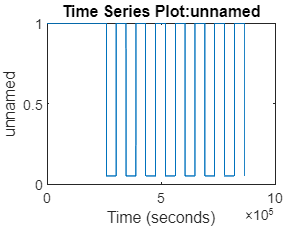

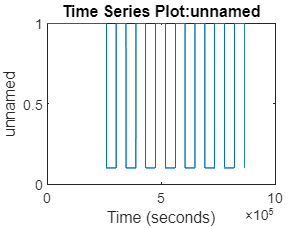

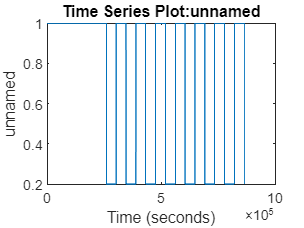

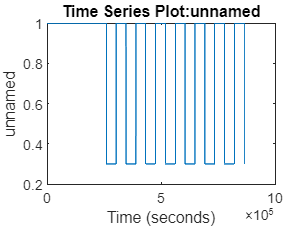

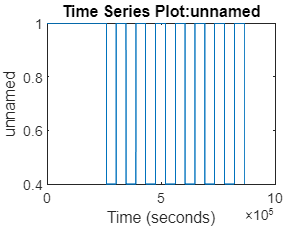

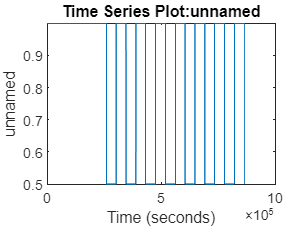

%Setup Run with power cycles

clear simIn

powerLeveList = [5,10,20,30,40,50]*0.01;

for j = 1:6

%create power signal
hour = 3600;
reducedFlow = 0.1;
day = 24*hour;
lowPowerLength = 12*hour;
lowPowerLevel = powerLeveList(j);
daily = [lowPowerLength,100, day-lowPowerLength-200,100];
dailyPower = [lowPowerLevel,1,1,lowPowerLevel];
%Run days
n_days = 7;
RunStamp = repmat(daily,1,n_days);
powerStamp = repmat(dailyPower,1,n_days);
timeLabel = [0, 3*day,100, RunStamp];
timeLabel = cumsum(timeLabel);
powerLabel = [1, 1,lowPowerLevel,powerStamp];
powerSignal = timeseries(powerLabel,timeLabel);
%powerSignal = setinterpmethod(powerSignal,'zoh');
figure
plot(powerSignal)

%targetGeneratorVoidFractionList = linspace(0,0.02,10);
reducedFlowList = linspace(lowPowerLevel,1,10);


%Only change void fraction list to modify the system efficiency
%A minimum of 0.1 flowrate is put on the pump

    for i = 1:length(reducedFlowList)
    
        simIn(10*(j-1)+i) = Simulink.SimulationInput('MSDRPrimaryLoop_LoadFollow_PostDefense');
        simIn(10*(j-1)+i) = simIn(10*(j-1)+i).setVariable('DXeG',1.63e-4);
        simIn(10*(j-1)+i) = simIn(10*(j-1)+i).setVariable('dMin',1e-4);
        simIn(10*(j-1)+i) = simIn(10*(j-1)+i).setVariable('targetGeneratorVoidFraction',0.02); 
        simIn(10*(j-1)+i) = simIn(10*(j-1)+i).setVariable('reducedFlow',reducedFlowList(i));
        simIn(10*(j-1)+i) = simIn(10*(j-1)+i).setVariable('powerSignal',powerSignal);
        
    end

end

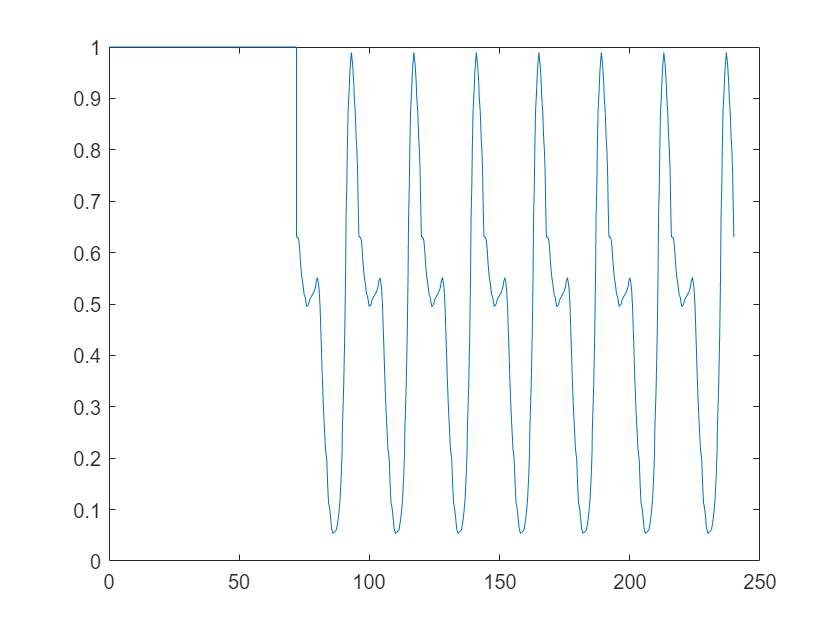

clear simIn
%Setup Run with sample duck curve


hour = 3600;
day = 24*hour;
daily = (SampleDuckCurve.Time)'*hour;
daily = [diff(daily),day-SampleDuckCurve.Time(end)*3600];
dailyPower = SampleDuckCurve.Power';
%Run days
n_days = 7;
RunStamp = repmat(daily,1,n_days);
powerStamp = repmat(dailyPower,1,n_days);
timeLabel = [0, 3*day,100, RunStamp];
timeLabel = cumsum(timeLabel);
powerLabel = [1, 1,dailyPower(1),powerStamp];
powerSignal = timeseries(powerLabel,timeLabel);
figure
plot(timeLabel/3600,powerLabel)



reducedFlowList = linspace(0.1,1,10);

    for i = 1:length(reducedFlowList)
    
        simIn(i) = Simulink.SimulationInput('MSDRPrimaryLoop_LoadFollow');
        simIn(i) = simIn(i).setVariable('DXeG',1.63e-4);
        simIn(i) = simIn(i).setVariable('dMin',1e-4);
        simIn(i) = simIn(i).setVariable('targetGeneratorVoidFraction',0.02); 
        simIn(i) = simIn(i).setVariable('reducedFlow',reducedFlowList(i));
        simIn(i) = simIn(i).setVariable('powerSignal',powerSignal);
        
    end


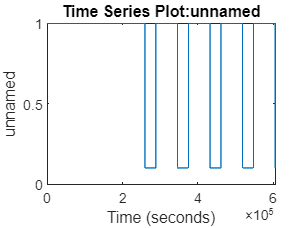

%Load-following sensitivity
clear simIn

%powerLeveList = [5,10,20,30,40,50]*0.01;
powerLevel = 0.1;

clear simIn

%overall scaling factors
dScale = 1;
dsmConst = 1e-3;
kScale = 1;
solubilityScale = 1;


shapeFactor = 0.04;
graphiteKDiff = 1.45e-8;

%Chem Sys Spec

pipeLineSectionList = 20*ones(1,10);
%pipeLineSectionList = 1:0.5:40.5;


pipeLineKLossList = (pipeLineSectionList-1).*(pipeLineSingleBendKLoss);
pipeLineKLossList = max(0.00001,pipeLineKLossList);
pipeLineLengthList = pipeLineSectionList*singleSectionLength;

pipeLineRefLength = 40 - pipePHXToReactorElevation;
pipeRefDiameter = 0.1;
%pipeLineDhList = sqrt(pipeLineRefLength./(pipeLineLengthList - pipePHXToReactorElevation))*pipeRefDiameter;
pipeLineDhList = ones(size(pipeLineSectionList))*pipeRefDiameter;
%pipeLineDhList = linspace(0.02,0.2,80);
pipeLineAreaList = 0.25*pi.*pipeLineDhList.^2;

pipeLineVolumeList = pipeLineLengthList.*pipeLineAreaList;

generatorDsmList = 0.001*ones(size(pipeLineSectionList));
%generatorDsmList = linspace(1e-4,1e-2,80);

%targetGeneratorVoidFractionList = ones(size(pipeLineSectionList))*0.02;
targetGeneratorVoidFractionList = linspace(0,0.1,10);


hour = 3600;
reducedFlow = 0.1;
day = 24*hour;
lowPowerLength = 8*hour;
lowPowerLevel = powerLevel;
daily = [lowPowerLength,100, day-lowPowerLength-200,100];
dailyPower = [lowPowerLevel,1,1,lowPowerLevel];
%Run days
n_days = 4;
RunStamp = repmat(daily,1,n_days);
powerStamp = repmat(dailyPower,1,n_days);
timeLabel = [0, 3*day,100, RunStamp];
timeLabel = cumsum(timeLabel);
powerLabel = [1, 1,lowPowerLevel,powerStamp];
powerSignal = timeseries(powerLabel,timeLabel);
%powerSignal = setinterpmethod(powerSignal,'zoh');
figure
plot(powerSignal)

%reducedFlowList = linspace(lowPowerLevel,1,10);
%Only change void fraction list to modify the system efficiency
%A minimum of 0.1 flowrate is put on the pump

    for i = 1:length(targetGeneratorVoidFractionList)
    
        
        simIn(i) = Simulink.SimulationInput('MSDRPrimaryLoop_LoadFollow');

        simIn(i) = simIn(i).setVariable('DXeG',1.63e-4);
        simIn(i) = simIn(i).setVariable('dMin',1e-4);
        simIn(i) = simIn(i).setVariable('dScale',dScale);
        
        simIn(i) = simIn(i).setVariable('bypassRatio',0.1);
    
        simIn(i) = simIn(i).setVariable('bubbleGeneratorDh',pipeLineDhList(i)); 
        simIn(i) = simIn(i).setVariable('bubbleGeneratorArea',pipeLineAreaList(i)); 
        simIn(i) = simIn(i).setVariable('generatorDsm',generatorDsmList(i)); 
        simIn(i) = simIn(i).setVariable('targetGeneratorVoidFraction',targetGeneratorVoidFractionList(i)); 
    
        simIn(i) = simIn(i).setVariable('bubbleSeparatorDiameter',pipeLineDhList(i)); 
        simIn(i) = simIn(i).setVariable('bubbleSeparatorArea',pipeLineDhList(i).^2*0.25*pi); 
        simIn(i) = simIn(i).setVariable('bubbleSeparatorDo',0.1*pipeLineDhList(i)); 
    
        simIn(i) = simIn(i).setVariable('pipeLineDh',pipeLineDhList(i)); 
        simIn(i) = simIn(i).setVariable('pipeLineArea',pipeLineAreaList(i)); 
        simIn(i) = simIn(i).setVariable('pipeLineKLoss',pipeLineKLossList(i)); 
        simIn(i) = simIn(i).setVariable('pipeLineLength',pipeLineLengthList(i)); 
        simIn(i) = simIn(i).setVariable('pipeLineVolume',pipeLineVolumeList(i)); 
        
        simIn(i) = simIn(i).setVariable('flowRatio',lowPowerLevel);
        simIn(i) = simIn(i).setVariable('powerSignal',powerSignal);
        
    end


[09-Apr-2024 00:42:45] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
[09-Apr-2024 00:43:50] Starting Simulink on parallel workers...
[09-Apr-2024 00:44:24] Loading project on parallel workers...
[09-Apr-2024 00:44:24] Configuring simulation cache folder on parallel workers...
[09-Apr-2024 00:44:37] Transferring base workspace variables used in the model to parallel workers...
[09-Apr-2024 00:45:58] Loading model on parallel workers...
[09-Apr-2024 00:47:38] Running simulations...
[09-Apr-2024 01:21:08] Completed 1 of 10 simulation runs
[09-Apr-2024 01:21:39] Completed 2 of 10 simulation runs
[09-Apr-2024 01:21:39] Completed 3 of 10 simulation runs
[09-Apr-2024 01:21:40] Completed 4 of 10 simulation runs
[09-Apr-2024 01:21:45] Completed 5 of 10 simulation runs
[09-Apr-2024 01:21:46] Completed 6 of 10 simulation runs
[09-Apr-2024 01:38:50] Completed 7 of 10 simulation run

[09-Apr-2024 01:38:53] Cleaning up parallel workers...


     1

     2

     8

    13

    14

    17

    18

    19

    21

    22

    24

    25

    27

    28

    29

    35

    36

    37

    38

    41

    43

    44

    45

    46

    49

    51

    55

    57

    58

    62

    64

    65

    67

    68

    70

    72

    75

    76

    77

    79

    80



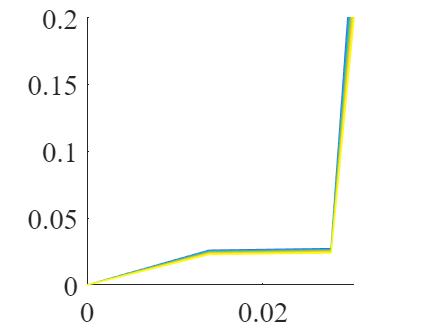

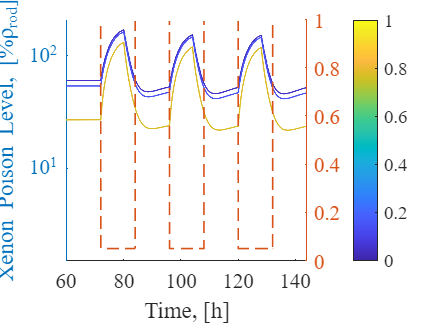

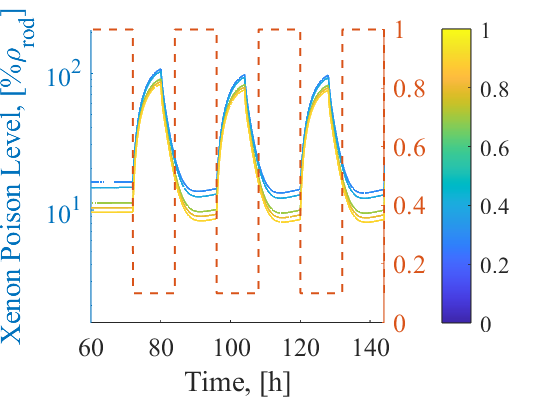

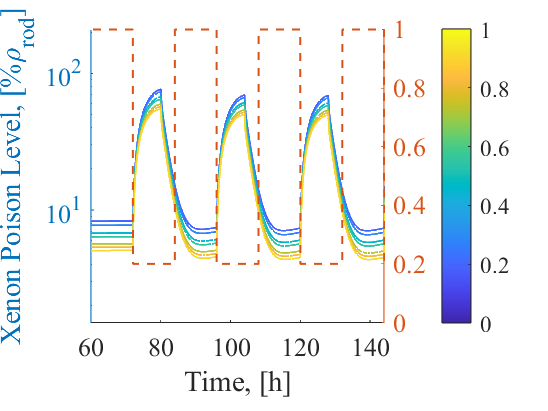

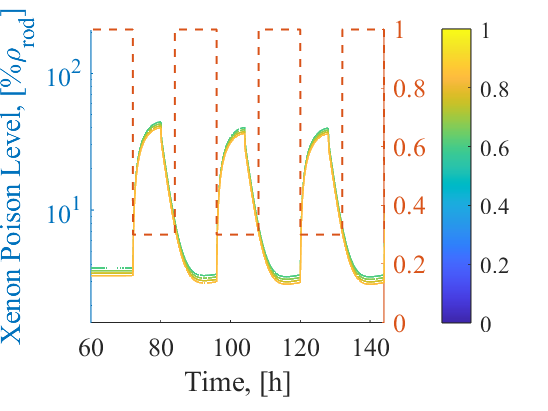

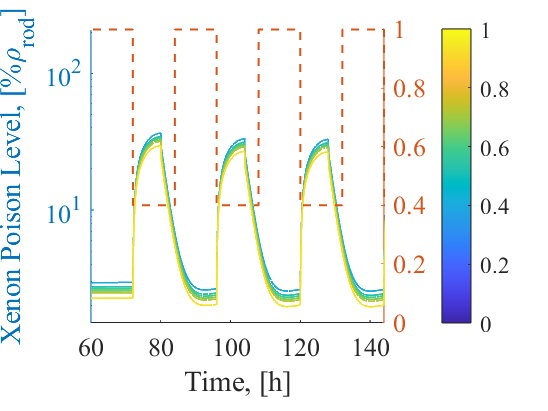

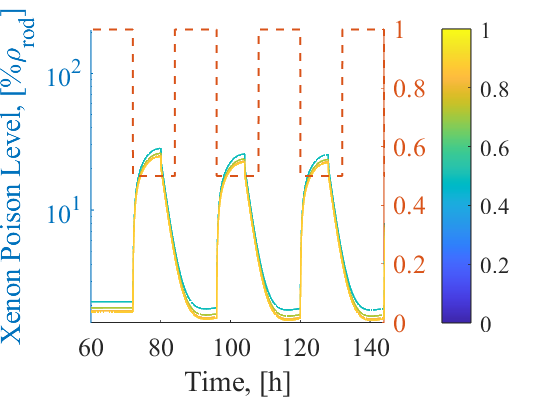

outData = parsim(simIn,'ShowProgress', 'on','TransferBaseWorkspaceVariables','on');

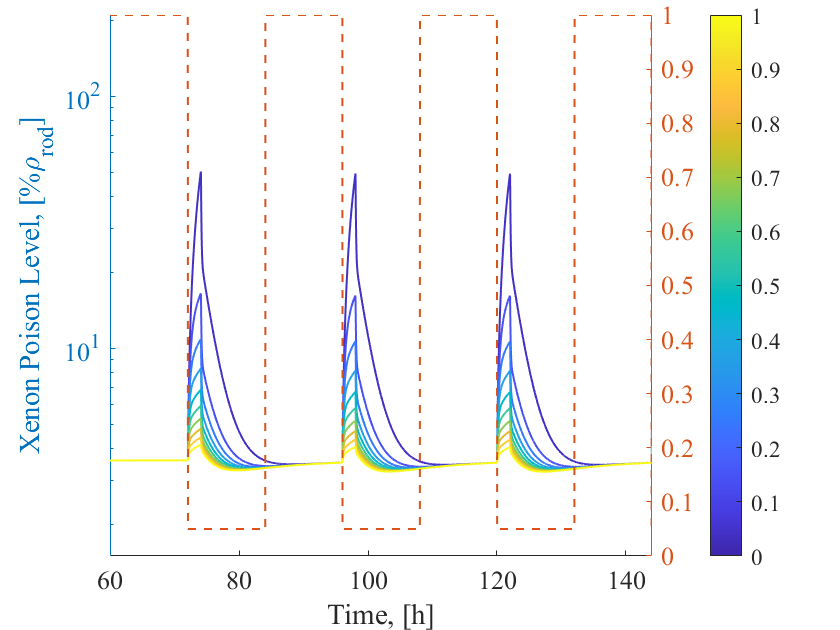

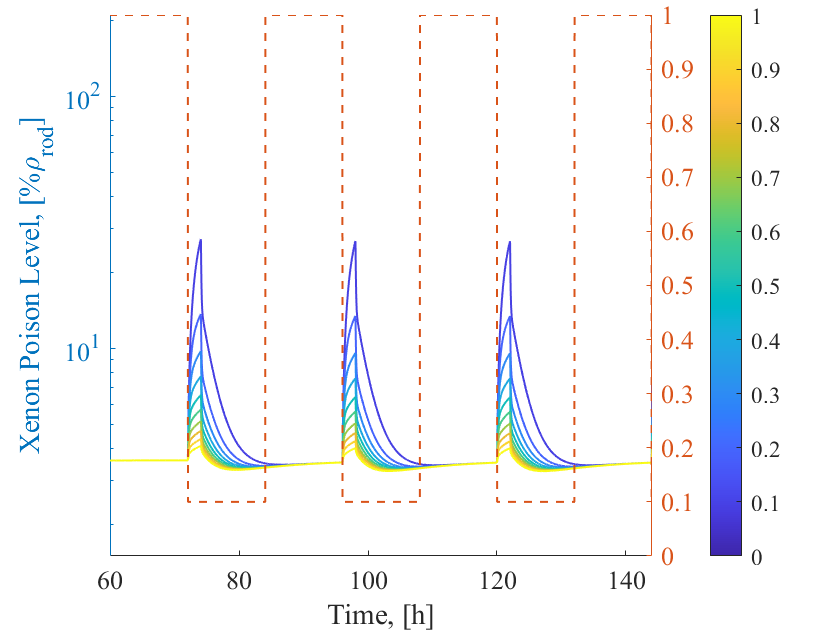

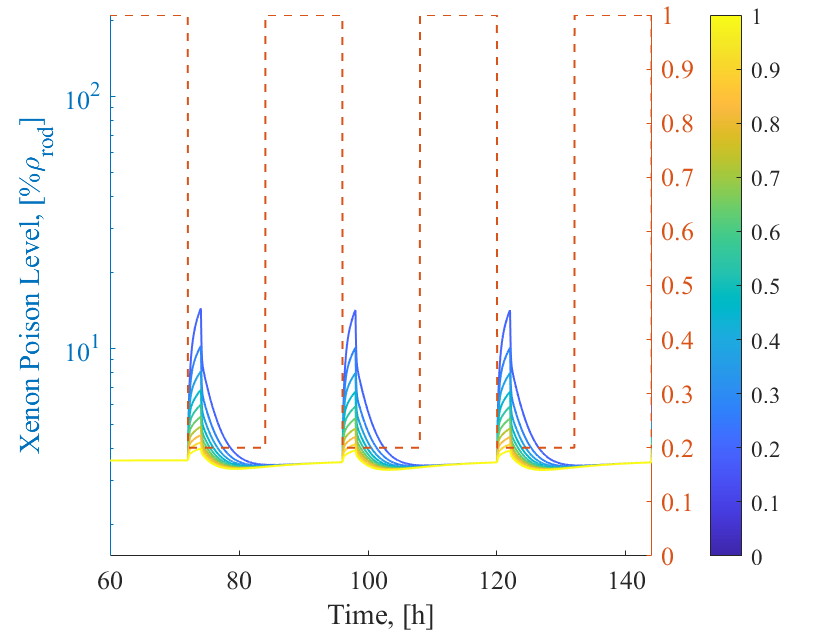

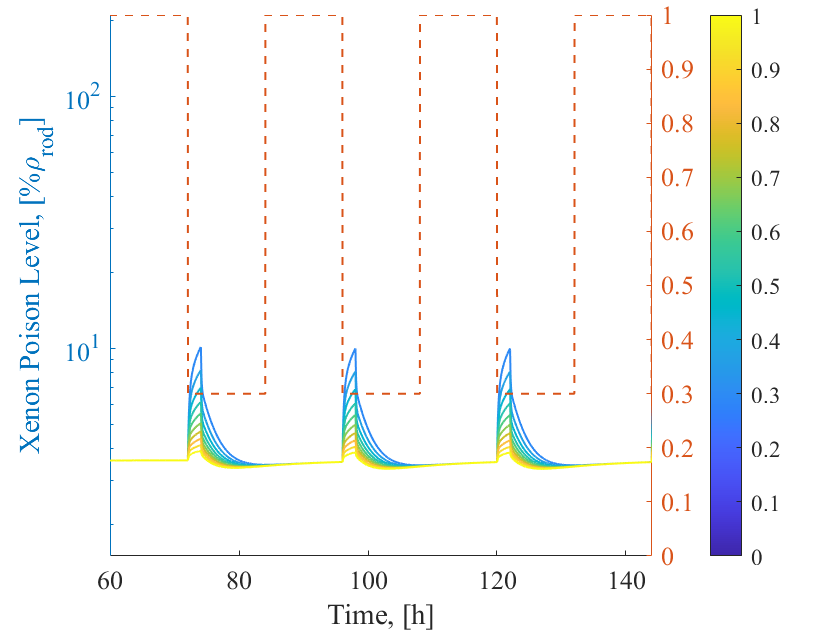

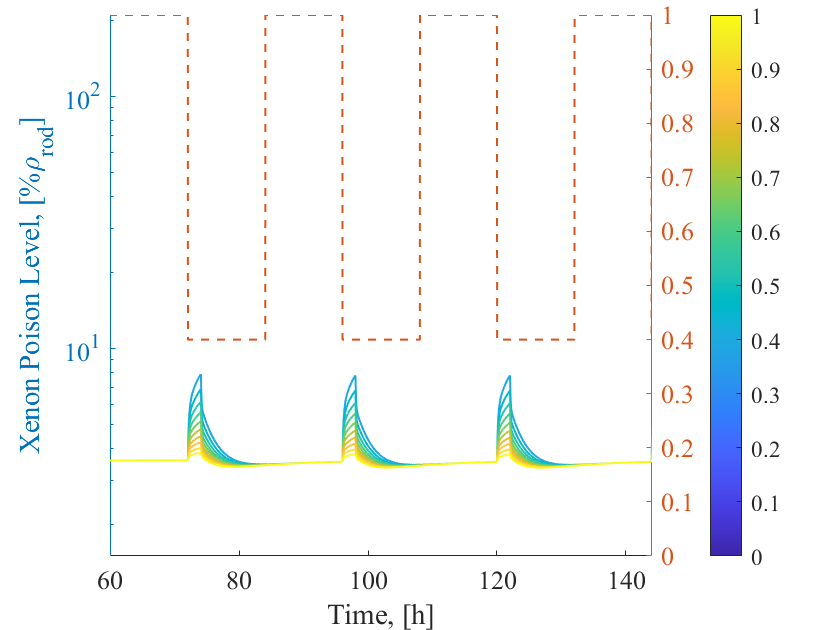

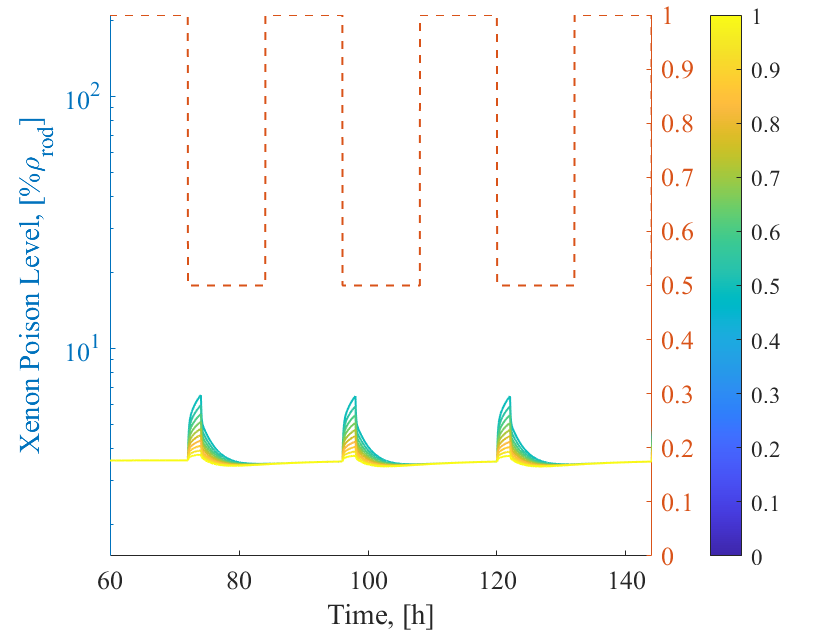

%Sample Processing code, used to produce Figure 13 and Appendix A
%Dependes on outData Structure, only for reference

clear SSPoisonListCross
SSPoisonListCross = zeros(6,10);
powerGrid = SSPoisonListCross;
flowGrid = powerGrid;

rodWorth = 0.65*4.249; %Wrong, but there is a *100 to compensate for it
colorMap = parula(100);

for j = 1:6

hour = 3600;
day = 24*hour;

lowPowerLength = 12*hour;
lowPowerLevel = powerLeveList(j);
daily = [lowPowerLength,100, day-lowPowerLength-200,100];
dailyPower = [lowPowerLevel,1,1,lowPowerLevel];
%Run days
n_days = 7;
RunStamp = repmat(daily,1,n_days);
powerStamp = repmat(dailyPower,1,n_days);
timeLabel = [0, 3*day,100, RunStamp];
timeLabel = cumsum(timeLabel);
powerLabel = [1, 1,lowPowerLevel,powerStamp];

figure()
hold on
ylabel('Xenon Poison Level, [%\rho_{rod}]')
ax = gca;
ax.YScale = 'log';
ylim([1.5,210]);
reducedFlowList = linspace(lowPowerLevel,1,10);

    

    for jj = 1:length(reducedFlowList)
    
        i = 10*(j-1) + jj;

        if isempty(outData(i).ErrorMessage)

            xenonMassSalt(i) = outData(i).coreXenonMass_Salt.Data(end);
            xenonMassGas(i) = outData(i).coreXenonMass_Gas.Data(end);
            xenonMassGraphite(i) = outData(i).coreXenonMass_Graphite.Data(end);
            name = ['LowestFlow=',num2str(reducedFlowList(jj),3)];
            T = outData(i).coreXenonMass_Salt.Time;
            xenonMassSaltT = outData(i).coreXenonMass_Salt.Data;
            xenonMassGasT = outData(i).coreXenonMass_Gas.Data;
            xenonMassGraphiteT = outData(i).coreXenonMass_Graphite.Data;
            crossSectionBasedReactivityT = (xenonMassSaltT+xenonMassGasT+xenonMassGraphiteT)*sigmaXe135*6.022e23*1000/135/(nuU235*totalFissionCrossSection)*100;
            yyaxis left
            colorIndex = floor(reducedFlowList(jj)*100);
            plot(T/3600,crossSectionBasedReactivityT./rodWorth*100,'DisplayName',name,'Color',colorMap(colorIndex,:),'LineStyle','-','LineWidth',1,'Marker','none');
            
            rangeIndex = T>110*hour & T<150*hour;
            SSPoisonListCross(j,jj) = max(crossSectionBasedReactivityT(rangeIndex));
            flowGrid(j,jj) = reducedFlowList(jj);
            powerGrid(j,jj) = lowPowerLevel;
            
            byPassList(i) = outData(i).divertedFlowRate.Data(end);
            RunIndex(i) = 1;

        else
            continue
        end
        
    end
    xlim([60 144]);
    
    c = colorbar;
    caxis([0, 1])
    %c.Label.String = 'Lowest Flow Ratio, []';
    yyaxis right
    plot(timeLabel/3600,powerLabel,'LineStyle','--','LineWidth',1,'Marker','none');
    ylim([0,1]);
    ax = gca;
    ax.FontName = 'Times';
    ax.FontSize = 13;
    set(gca,'looseInset',[0 0 0 0.02]);
    pbaspect([1 1 1]);
    xlabel('Time, [h]')
    %ylabel('Power Level, []')
%     saveas(gcf,[num2str(lowPowerLength/hour,'%2d'),'hour-',num2str(lowPowerLevel*100,'%2d'),'power.svg']);
%     savefig(gcf,[num2str(lowPowerLength/hour,'%2d'),'hour-',num2str(lowPowerLevel*100,'%2d'),'power.fig']);
end

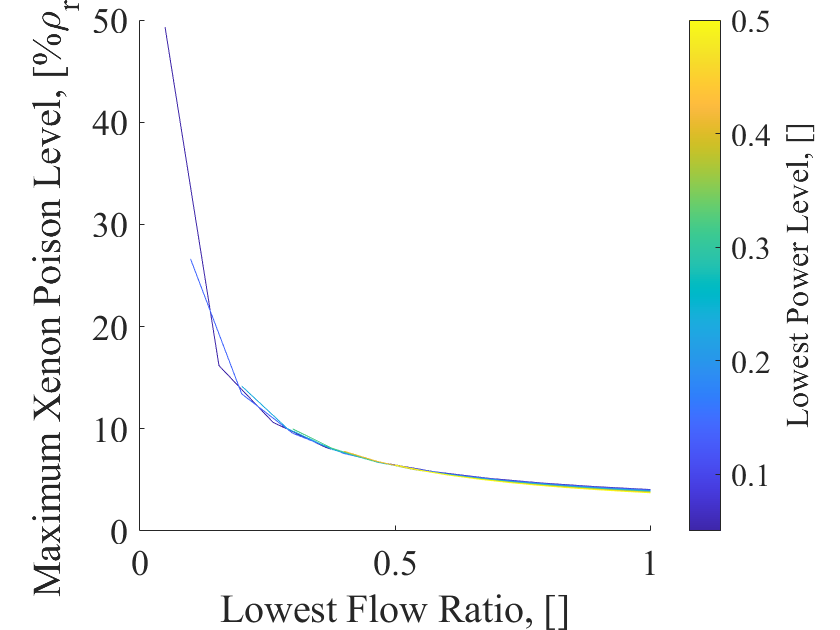

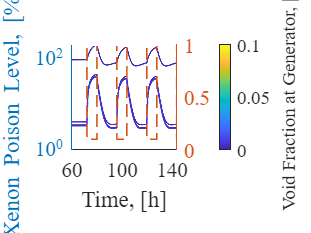

%Packed code, used for Figure 14. 

ColorMap = parula(6);
figure
hold on
for j = 1:6
     plot(flowGrid(j,:),SSPoisonListCross(j,:)./rodWorth*100,'Color',ColorMap(j,:))
end
c = colorbar;
caxis([0.05, 0.5])
c.Label.String = 'Lowest Power Level, []';
ax = gca;
ax.FontName = 'Times';
ax.FontSize = 18;
set(gca,'looseInset',[0 0 0 0.02]);
pbaspect([1 1 1]);
xlabel('Lowest Flow Ratio, []')
ylabel('Maximum Xenon Poison Level, [%\rho_{rod}]');